clc
clear

load cog_Bike.mat 
load inertia_Bike.mat

mf = 2.02 %2.02*8

mf = 2.0200

ri=0.05

ri = 0.0500

ro=0.153

ro = 0.1530


h= 0.25

h = 0.2500

mb = 94;

Ip=1/2*mf*(ro^2+ri^2)

Ip = 0.0262

Ir=1/12*mf*(3*(ro^2+ri^2)+h^2)

Ir = 0.0236

hb = -cog_Bike(3)

hb = 0.8612

hf= 1.2

hf = 1.2000

Ib = inertia_Bike(1,1)

Ib = 9.4597

% Ip = 0.0088*8
% Ir = 0.0224*8
w = 469

w = 469

L = 0.000119

L = 1.1900e-04

R = 0.61

R = 0.6100

Bm = 0.003

Bm = 0.0030

Km = 0.0259

Km = 0.0259

Ke = 0.0027

Ke = 0.0027

g = 9.81

g = 9.8100

A =[ 0 1 0 0;
    g*(mb*hb+mf*hf)/(mb*hb^2+mf*hf^2+Ib + Ir) 0 Ip*w/(mb*hb^2+mf*hf^2+Ib + Ir) 0;
    0 -Ip*w/Ir -Bm/Ir 65*Km/Ir;
    0 0 -Ke/L -R/L];
B = [0;0;0;1/L];
C = [1 0 0 0];
D = 0;
system= ss(A,B,C,D) % uncompensated system (no controller)


system =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2    9.962        0   0.1495        0
   x3        0   -519.9  -0.1271    71.32
   x4        0        0   -22.69    -5126
 
  B = 
         u1
   x1     0
   x2     0
   x3     0
   x4  8403
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



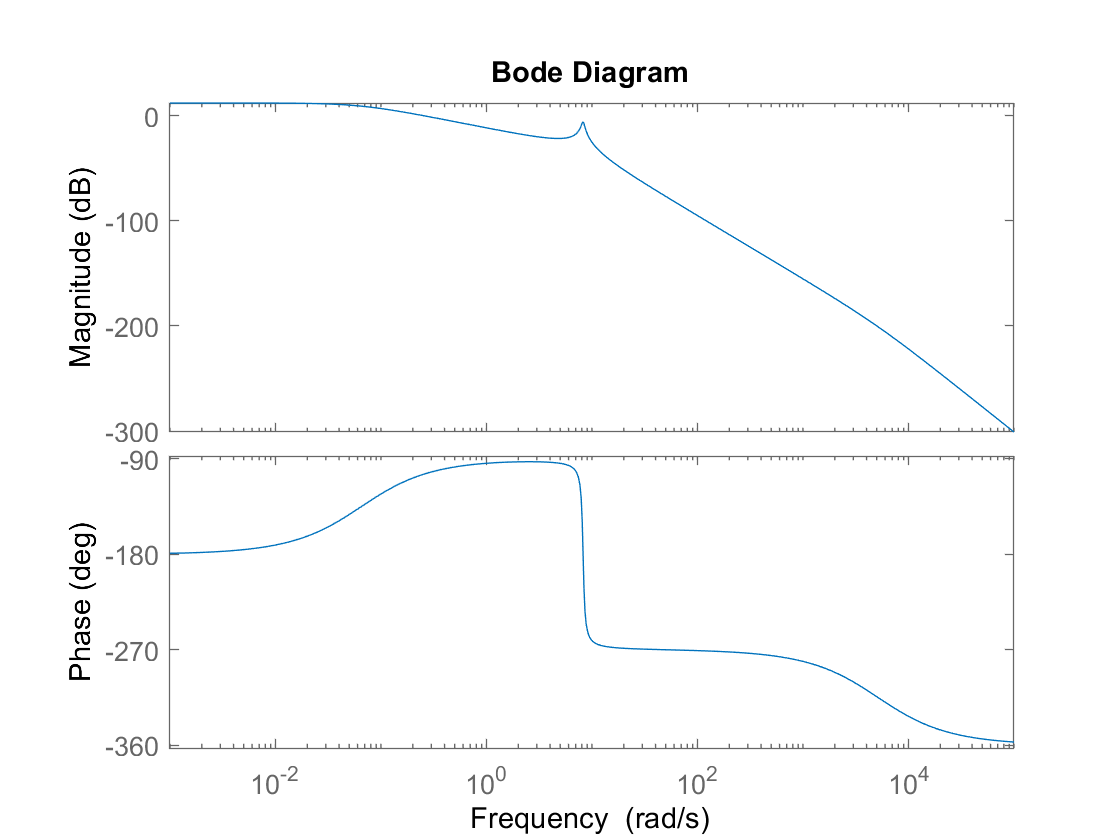


bode(system)

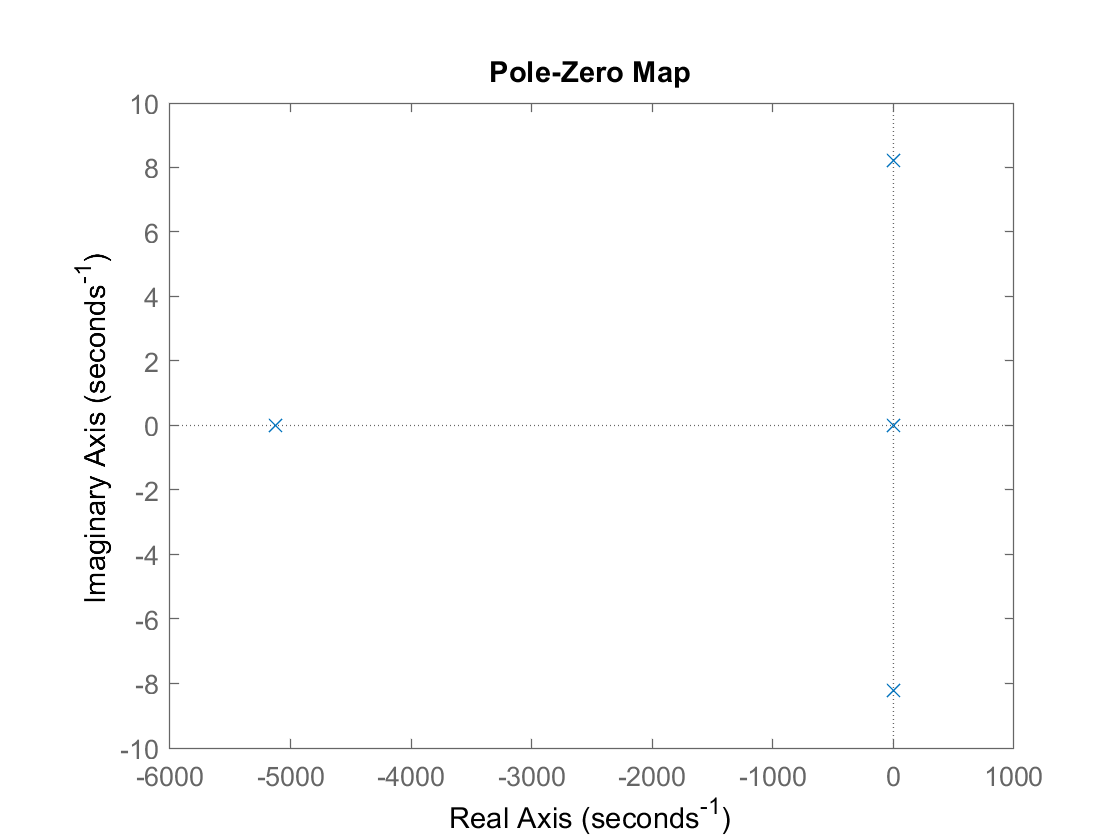

pzmap(system)

[num,den]=ss2tf(A,B,C,D)

num = 	1.0e+04 *

         0         0         0         0    8.9587


den = 	1.0e+05 *

    0.0000    0.0513    0.0234    3.4732   -0.2261


tfunction= tf(num,den)


tfunction =
 
                      8.959e04
  -------------------------------------------------
  s^4 + 5126 s^3 + 2337 s^2 + 3.473e05 s - 2.261e04
 
Continuous-time transfer function.




load PIDFcontroller.mat;
PIDFController


PIDFController =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 3.05, Ki = 0.0511, Kd = -0.882, Tf = 0.305
 
Continuous-time PIDF controller in parallel form.




compensatedsys=PIDFController*tfunction;

fb =feedback(compensatedsys,1)


fb =
 
                        1.465e04 s^2 + 9.012e05 s + 1.502e04
  ---------------------------------------------------------------------------------
  s^6 + 5129 s^5 + 1.914e04 s^4 + 3.55e05 s^3 + 1.13e06 s^2 + 8.271e05 s + 1.502e04
 
Continuous-time transfer function.



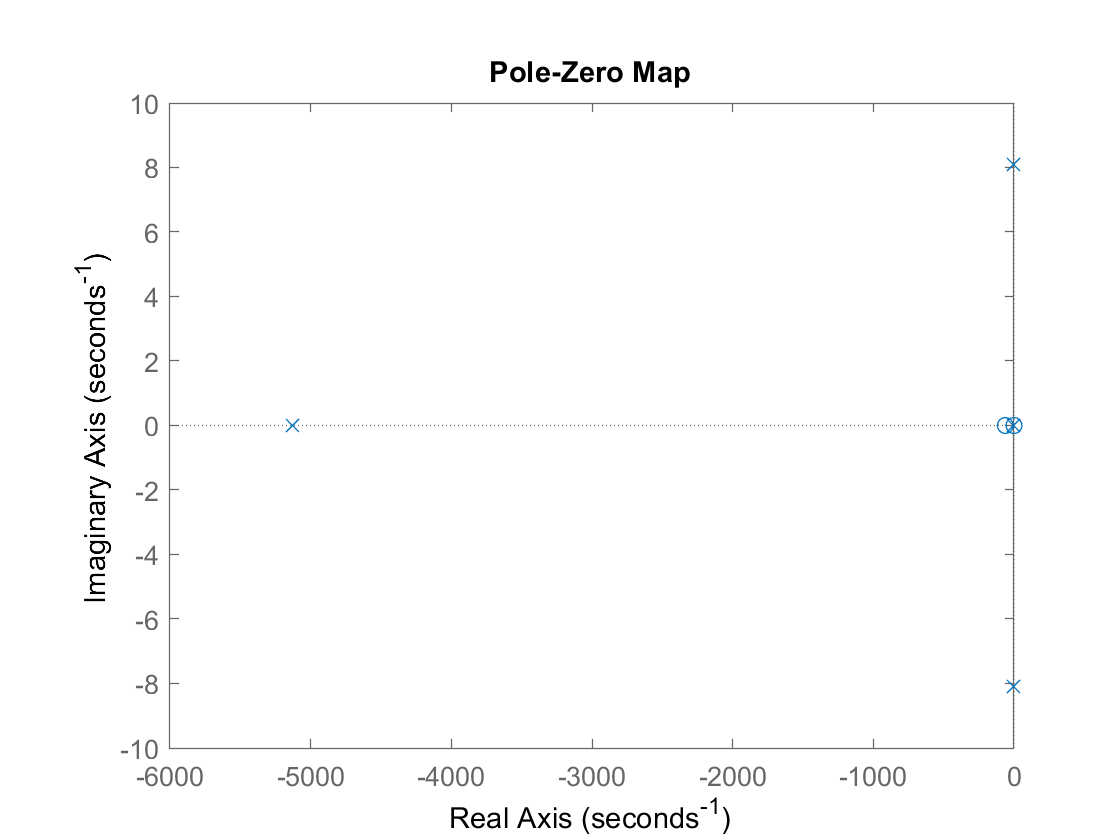

figure
pzmap(fb)


u= zeros(1,10001);
T = 0:0.01:100

T =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u(1:1000)= 1

u =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


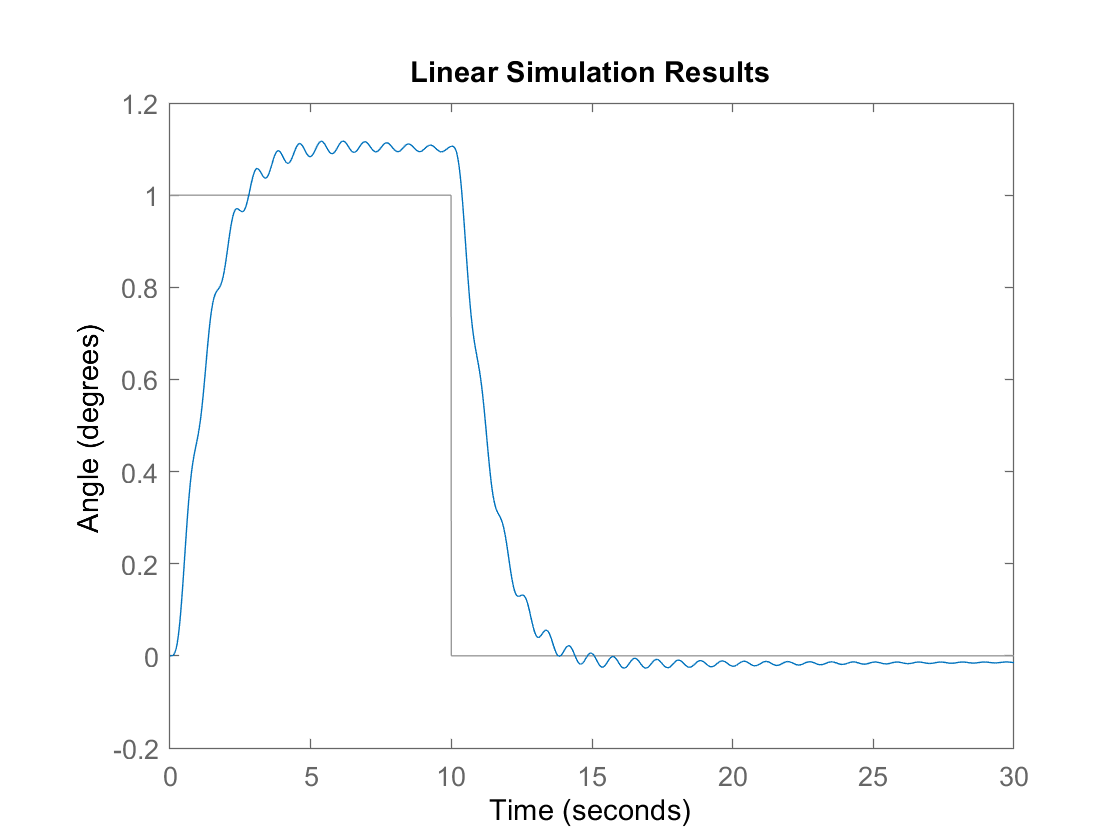


figure
lsim(fb,u,T,[10^5;10^3 ;10^3;10^4;10^5;10^5])
xlim([0,30])
ylabel('Angle (degrees)')

fb3=fb


fb3 =
 
                        1.465e04 s^2 + 9.012e05 s + 1.502e04
  ---------------------------------------------------------------------------------
  s^6 + 5129 s^5 + 1.914e04 s^4 + 3.55e05 s^3 + 1.13e06 s^2 + 8.271e05 s + 1.502e04
 
Continuous-time transfer function.



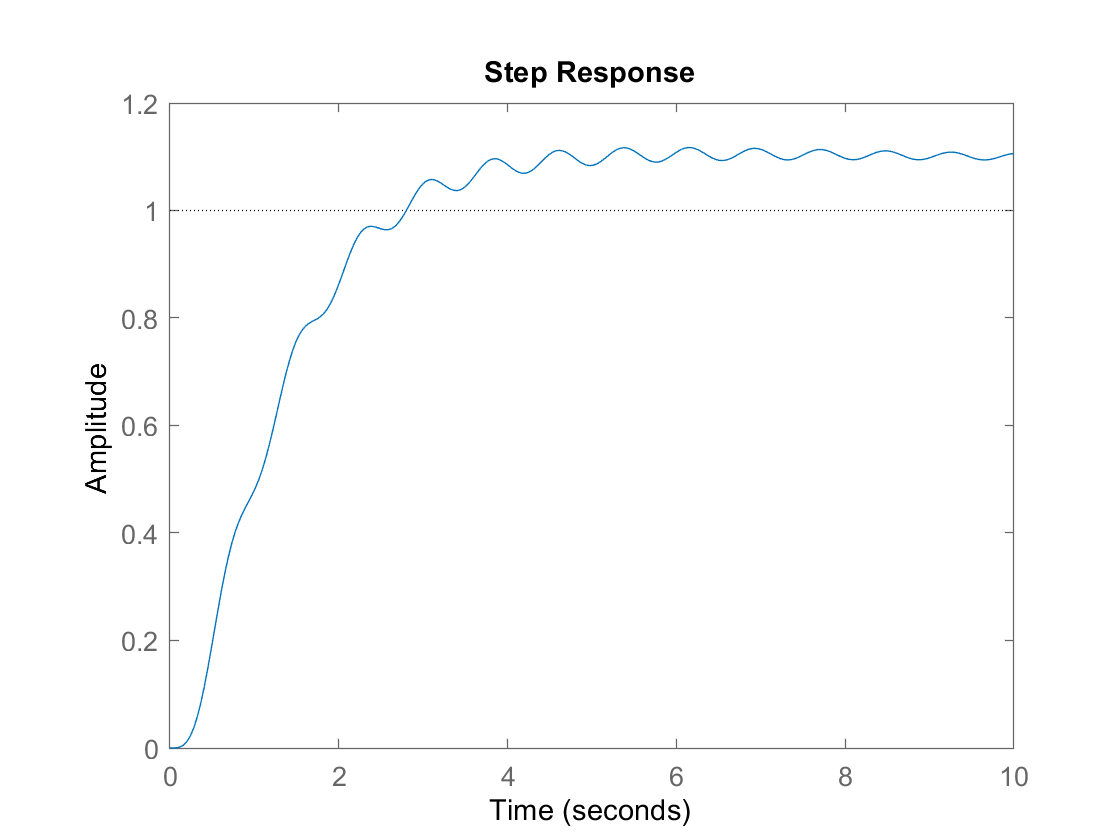

figure
step(fb)
xlim([0,10])